# Ejercicio 3.05  

Usa la Robotics System Toolbox v2.2

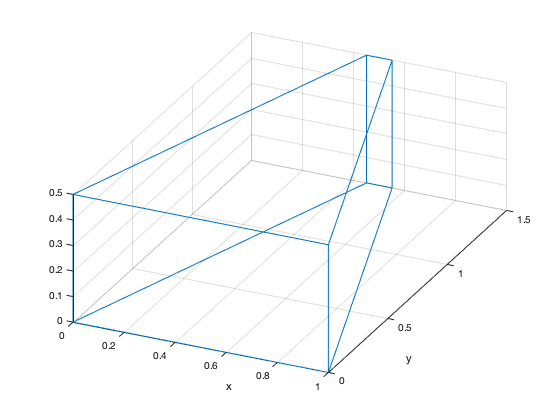

% Lectura del archivo de datos. Se incluye un script generado por la
% herramienta de importación de datos de matlab.
tray_solidorigido_importar;
AA=table2array(traysolidorigido);

% Representamos el sólido rígido de manera conveniente:
P=psolido;
Pp=P'; plot3(Pp(:,1), Pp(:,2),Pp(:,3))
axis equal; grid
view(25,25); hold on
xlabel('x'); ylabel('y'); 

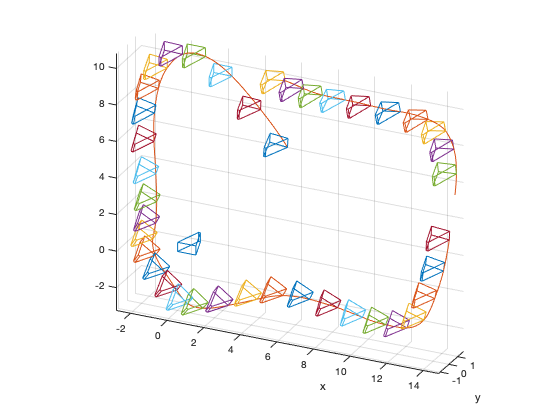


%% Escogemos sólo un rango de los datos disponibles para que la representación sea más clara:
ini=1000;
fin=1600;

% Representamos sólo la trayectoria:
plot3(AA(ini:fin,6)/100,AA(ini:fin,7)/100,AA(ini:fin,8)/100)
% Representamos el sólido (solo uno de cada 15 por claridad):
for i=ini:15:fin,
    posic=[AA(i,6) AA(i,7) AA(i,8)]/100;

    % Ponemos el sólido en homogéneas:
    P=psolido;
    Ph = cart2hom(P');
    Ph=Ph';

    % Convertimos posición y cuaternión en una matriz homogénea:
    T1=trvec2tform( posic );
    T2=quat2tform([AA(i,2) AA(i,3) AA(i,4) AA(i,5)]);
    T=T1*T2;

    % calculamos la transformación y representamos el sólido:
    Ph  = T * Ph;       
    Pp=Ph'; plot3(Pp(:,1),Pp(:,2),Pp(:,3),'-')
end
view(25,25)